% PHYS 434 Homework 2
% 10/13/2019 (Mon)
% Jin Kyoung Lee

% 1. Which is more probable when rolling 2 six-sided dice:
% rolling snake eyes (two ones) or rolling sevens (dice sum
% to seven)? What is the ratio of the probabilities?

% Probability of getting 1 when rolling a dice: 1/6
% Therefore, the probability of rolling snake eyes is:
pSnakeEyes = (1/6)*(1/6)

pSnakeEyes = 0.0278

% Probability of rolling sevens:
% When rolling 2 dice, there are 6 possible outcomes that
% makes 7: (1,6), (2,5), (3,4), (4,3), (5,2), (6,1)
% Therefore, the probability of rolling sevens is:
pRollingSevens = 6 / 36

pRollingSevens = 0.1667

% The probability of rolling snake eyes is 2.78% and the
% probability of rolling sevens is 16.67%

% The ratio of the probabilties is:
pRatio = pRollingSevens/pSnakeEyes

pRatio = 6

% Therefore, pRollingSevens = 6*pSnakeEyes


% 2. Show how to use the convolution operator to determine
% the probability of the sum of 2 six sided dice.

% Analytical calculation:
% When rolling 2 dice, the sum of two dice(x) can be:
% 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12
% (The probability of getting the sum 0 is 0 because the least
% value we can get from a die is 1)
% And, possible outcomes and probability(p(x)) for each sum are:
% 2: 1+1 / p(2) = (1/6)*(1/6) = 1/36
% 3: 1+2, 2+1 / p(3) = [(1/6)*(1/6)]+[(1/6)*(1/6)] = 2/36
% 4: 1+3, 2+2, 3+1 / p(4) = 3*[(1/6)*(1/6)] = 3/36
% 5: 1+4, 2+3, 3+2, 4+1 / p(5) = 4/36
% 6: 1+5, 2+4, 3+3, 4+2, 5+1 / p(6) = 5/36
% 7: 1+6, 2+5, 3+4, 4+3, 5+2, 6+1 / p(7) = 6/36
% 8: 2+6, 3+5, 4+4, 5+2, 6+1 / p(8) = 5/36
% 9: 3+6, 4+5, 5+4, 6+3 / p(9) = 4/36
% 10: 4+6, 5+5, 6+4 / p(10) = 3/36
% 11: 5+6, 6+5 / p(11) = 2/36
% 12: 6+6 / p(12) = 1/36

% x = sum of two dice
%P_A+B(x) = ∑_z[p_A(z)*p_B(x-z)]

% Numerical (computer program) calculation:
% The probability of rolling 1 die:
die1 = zeros(201,1);
for x = 1:6
    die1(x+100) = 1/6;
end
die1(101:106,1)

ans =     0.1667
    0.1667
    0.1667
    0.1667
    0.1667
    0.1667


sumOfProbability1 = sum(die1)

sumOfProbability1 = 1.0000

% Rolling 2 dice:
% The probability of rolling 2 dice
dice2 = zeros(201,1);
for x = 0:99
    dice2(x+100) = 0;
    for k = 0:99
        dice2(x+100) = dice2(x+100)+ die1(k+100) * die1(x-k+100);
    end
end
dice2(102:112,1)

ans =     0.0278
    0.0556
    0.0833
    0.1111
    0.1389
    0.1667
    0.1389
    0.1111
    0.0833
    0.0556


sumOfProbability2 = sum(dice2)

sumOfProbability2 = 1.0000

% 3. Calculate the mean and the variance of the distribution
% in problem 2.
% The mean of the distribution:
% mu = ∑[x*p(x)]
mu = zeros(11,1);
for x = 2:12
    mu(x) = x * dice2(x+100);
end
mean = sum(mu)

mean = 7

% The variance of the distribution:
% variance = [∑(x-mu)^2]/n-1, where n is the sample size
var2dice = zeros(11,1);
for x = 2:12
    var2dice(x) = (x-mean)^2;
end
variance = sum(var2dice)./10 % n=11

variance = 11

% 4. Graph the average of 10 dice.
% The least sum getting from rolling 10 dice: 1*10 = 10
% the greatest sum getting from rolling 10 dice: 6*10 = 60
% ============================================================
% The probability of rolling 3 dice
dice3 = zeros(201,1);
for x = 0:99
    dice3(x+100) = 0;
    for k = 0:99
        dice3(x+100) = dice3(x+100)+ dice2(k+100) * die1(x-k+100);
    end
end
% The probability of rolling 4 dice
dice4 = zeros(201,1);
for x = 0:99
    dice4(x+100) = 0;
    for k = 0:99
        dice4(x+100) = dice4(x+100)+ dice3(k+100) * die1(x-k+100);
    end
end
% The probability of rolling 5 dice
dice5 = zeros(201,1);
for x = 0:99
    dice5(x+100) = 0;
    for k = 0:99
        dice5(x+100) = dice5(x+100)+ dice4(k+100) * die1(x-k+100);
    end
end
% The probability of rolling 6 dice
dice6 = zeros(201,1);
for x = 0:99
    dice6(x+100) = 0;
    for k = 0:99
        dice6(x+100) = dice6(x+100)+ dice5(k+100) * die1(x-k+100);
    end
end
% The probability of rolling 7 dice
dice7 = zeros(201,1);
for x = 0:99
    dice7(x+100) = 0;
    for k = 0:99
        dice7(x+100) = dice7(x+100)+ dice6(k+100) * die1(x-k+100);
    end
end
% The probability of rolling 8 dice
dice8 = zeros(201,1);
for x = 0:99
    dice8(x+100) = 0;
    for k = 0:99
        dice8(x+100) = dice8(x+100)+ dice7(k+100) * die1(x-k+100);
    end
end
% The probability of rolling 9 dice
dice9 = zeros(201,1);
for x = 0:99
    dice9(x+100) = 0;
    for k = 0:99
        dice9(x+100) = dice9(x+100)+ dice8(k+100) * die1(x-k+100);
    end
end

% The probability of rolling 10 dice
dice10 = zeros(201,1);
for x = 0:99
    dice10(x+100) = 0;
    for k = 0:99
        dice10(x+100) = dice10(x+100)+ dice9(k+100) * die1(x-k+100);
    end
end
sum(dice10)

ans = 1.0000

% sample size = 51
% The mean:
mu10 = zeros (51,1);
for x = 10:60
    mu10(x) = x * dice10(x+100);
end
mean10 = sum(mu10)

mean10 = 35

% The variance:
var10dice = zeros(51,1);
for x = 10:60
    var10dice(x) = (x-mean10)^2;
end
variance10 = sum(var10dice)./50 % n=51

variance10 = 221

% Sigma:
sigma = sqrt(221)

sigma = 14.8661

dice10(110:160,1)

ans =     0.0000
    0.0002
    0.0009
    0.0036
    0.0118
    0.0331
    0.0826
    0.1875
    0.3929
    0.7677


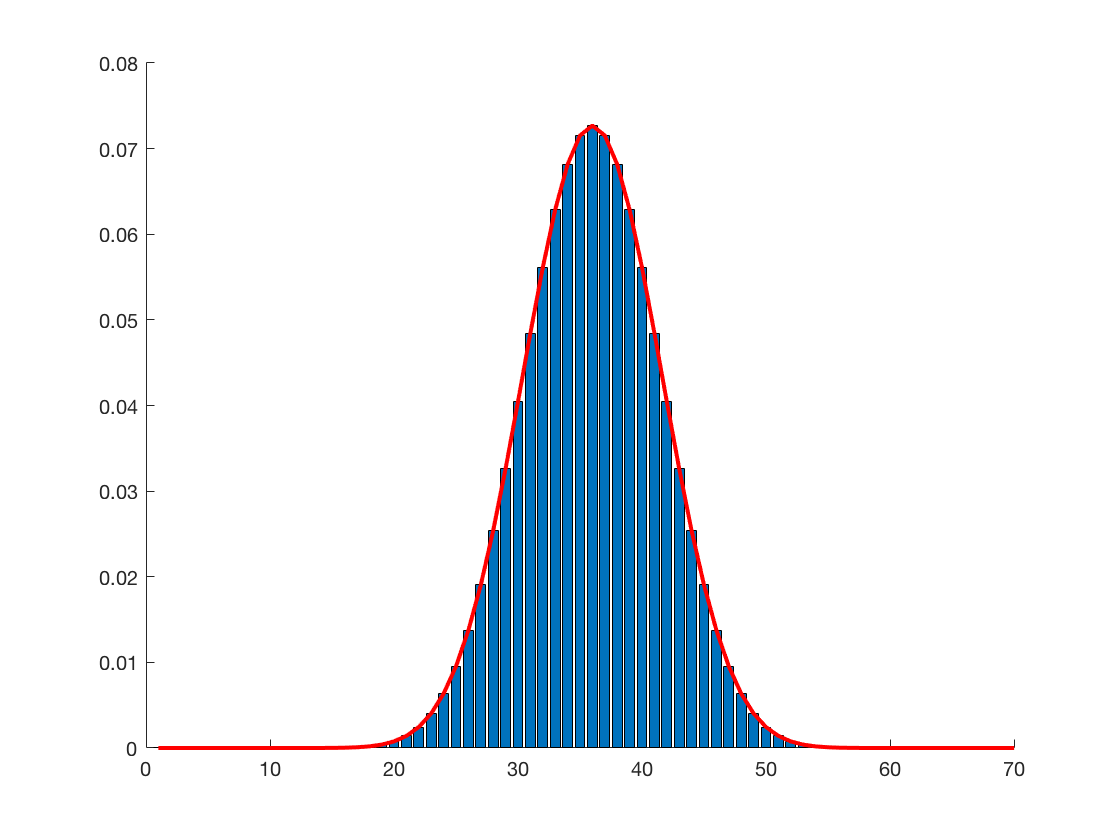

hold on
bar(dice10(100:170))
plot(dice10(100:170),"Red","LineWidth",2)
xlim([0,70])
ylim([0,0.08])
hold off

% Since it 